**LEP 5-3 : Plug Flow Reactor**

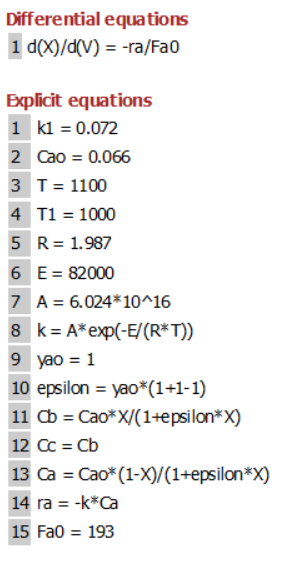

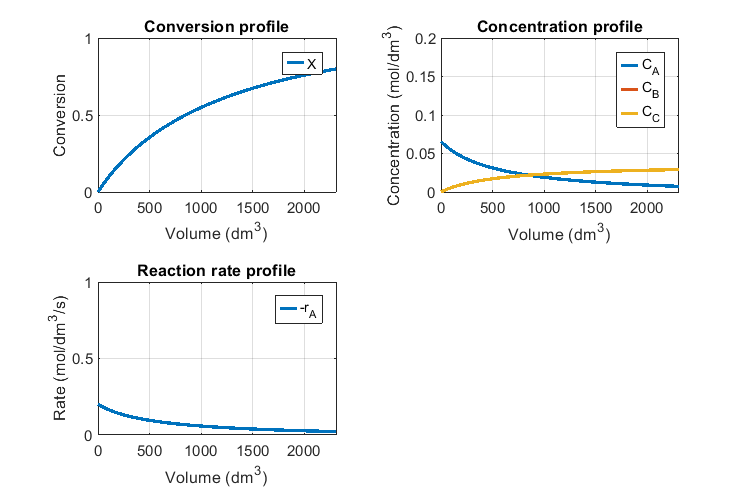

Vspan = [0 2310];  
y0 = [0]; 
P=6;
T = 1100;
E = 82000;
yao = 1;
Fao = 193;
[v,y]=ode45(@(v,y)ODEfun(v,y,T,P,E,yao,Fao),Vspan,y0);
tiledlayout(2,2)
set (gcf,'Position',[0,0.1,600,400])
nexttile
plot(v,y(:,1),'LineWidth',2)
xlabel('Volume (dm^3)')
ylabel('Conversion')
leg=legend('X');
leg.ItemTokenSize=[10,10];
axis([0 2310 0 1])
title('Conversion profile')
grid on
z=size(y);
Cto=P*10^5/(8.314*T)/1000;
Cao = yao*Cto;
epsilon = yao*(1+1-1); 
R = 1.987;
A=6.024*10^16;
k = A*exp(-E/(R*T));
for i=1 : z(1,1)
    % Calculating the values of rate from its expression 
Ca(i) = Cao*(1-y(i,1))/(1+epsilon*y(i,1));
ra(i) = -k*Ca(i);
Cb(i) = Cao*y(i,1)/(1+epsilon*y(i,1)); 
Cc(i) = Cb(i);
end
nexttile
plot(v,Ca(1:z(1,1)),v,Cb(1:z(1,1)),v,Cc(1:z(1,1)),'LineWidth',2)
xlabel('Volume (dm^3)')
ylabel('Concentration (mol/dm^3)')
leg=legend('C_A','C_B','C_C');
leg.ItemTokenSize=[10,10];
title('Concentration profile')
grid on
axis([0 2310 0 0.2])
nexttile
plot(v,-ra(1:z(1,1)),'LineWidth',2)
xlabel('Volume (dm^3)')
ylabel('Rate (mol/dm^3/s)')
leg=legend('-r_A');
leg.ItemTokenSize=[10,10];
title('Reaction rate profile')
grid on
axis([0 2310 0 1])

function dYfuncvecdV = ODEfun(V,Yfuncvec,T,P,E,yao,Fao)
X = Yfuncvec(1); 
% Explicit equations
R = 1.987;
Cto=P*10^5/(8.314*T)/1000;
Cao = yao*Cto;
epsilon = yao*(1+1-1); 
A=6.024*10^16;
k = A*exp(-E/(R*T));
Cb = Cao*X/(1+epsilon*X); 
Cc = Cb;
Ca = Cao*(1-X)/(1+epsilon*X); 
ra = -k*Ca; 
% Differential equations
dXdV = - (ra / Fao); 
dYfuncvecdV =[dXdV]; 
end
